[https://www.mathworks.com/help/vision/ug/semantic-segmentation-with-deep-learning.html#mw_6ab02754-d2fa-4330-8bea-3eeec77279da](https://www.mathworks.com/help/vision/ug/semantic-segmentation-with-deep-learning.html#mw_6ab02754-d2fa-4330-8bea-3eeec77279da)

%Desktop Eric => Laptop ABS 
gTruth = load("gTruth.mat");
gTruth = gTruth.gTruth;

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [4×6 table]
           LabelData: [26×1 table]


alternativePaths = ["C:\Users\esurprenant\repos\ConcreteAnalyser\matlab\labeling" "C:\Users\eric_\source\repos\Eric-Surprenant\ConcreteAnalyser\matlab\labeling"];
unresolvedPaths = changeFilePaths(gTruth,alternativePaths);


All the file paths are resolved in this groundTruth object.


alternativePaths = ["C:\Users\esurprenant\repos\ConcreteAnalyser\matlab\labeling\PixelLabelData" "C:\Users\eric_\source\repos\Eric-Surprenant\ConcreteAnalyser\matlab\labeling\PixelLabelData"];
unresolvedPaths = changeFilePaths(gTruth,alternativePaths);


All the file paths are resolved in this groundTruth object.


% save('gTruth.mat','-struct','gTruth');
save gTruth.mat gTruth
%Create an image and label datastore
[imds,pxds] = pixelLabelTrainingData(gTruth);

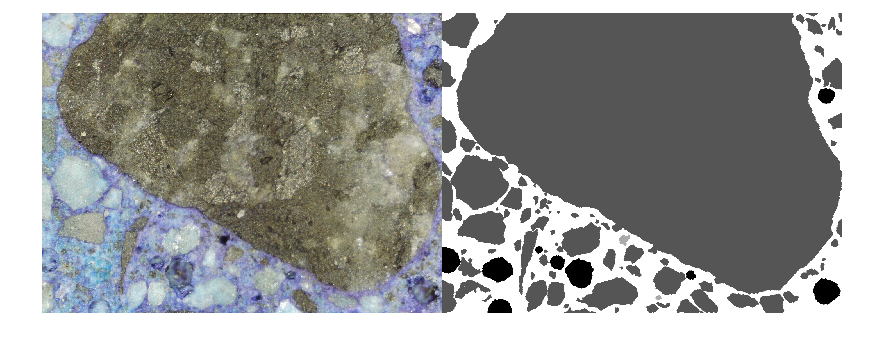

%Visualize training images and ground truth pixel labels.
I = read(imds);
C = read(pxds);
I = imresize(I,5);
L = imresize(uint8(C{1}),5);
figure, imshowpair(I,L,'montage')

%Create a semantic segmentation network. This network uses a simple
% semantic segmentation network based on a downsampling and upsampling design.
numFilters = 64;
filterSize = 3;
numClasses = 4;
layers = [
    imageInputLayer([1536 2048 3])
    convolution2dLayer(filterSize,numFilters,'Padding',1)
    reluLayer()
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(filterSize,numFilters,'Padding',1)
    reluLayer()
    transposedConv2dLayer(4,numFilters,'Stride',2,'Cropping',1);
    convolution2dLayer(1,numClasses);
    softmaxLayer()
    pixelClassificationLayer()
    ];

%Setup training options.
opts = trainingOptions('sgdm', ...
    InitialLearnRate=1e-3, ...
    MaxEpochs=100, ...
    MiniBatchSize=1, ...
    ExecutionEnvironment='cpu');
%     Plots="training-progress", ...

%Combine the image and pixel label datastore for training.
trainingData = combine(imds,pxds);


%Train the network. 
net = trainNetwork(trainingData,layers,opts);

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:10 |       22.90% |       4.1016 |          0.0010 |
|       2 |          50 |       00:08:40 |       48.48% |       1.2251 |          0.0010 |
|       3 |         100 |       00:17:12 |       91.33% |       0.2930 |          0.0010 |
|       4 |         150 |       00:25:20 |       84.41% |       0.4805 |          0.0010 |
|       5 |         200 |       00:33:47 |       22.65% |       2.4202 |          0.0010 |
|       7 |         250 |       00:42:12 |       53.18% |       1.0905 |          0.0010 |
|       8 |         300 |       00:50:35 |       91

%Save net
save net4.mat net

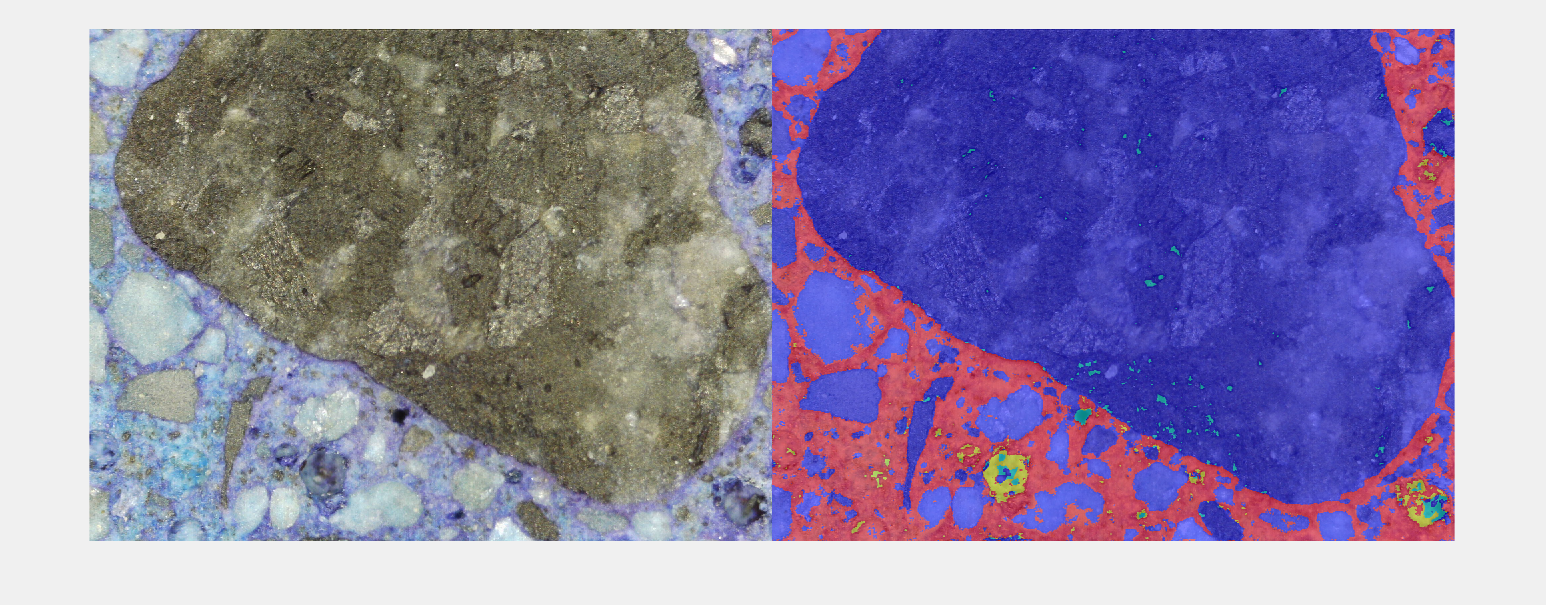

Error using semanticSegmentationMetrics
Expected input number 1, dsResults, to be one of these types:

cell, table

Instead its type was categorical.

Error in semanticSegmentationMetrics>@(x,validType,validAttribs,name,pos)validateattributes(x,validType,validAttribs,mfilename,name,pos) (line 1072)
            validateInput = @(x,validType,validAttribs,name,pos) validateattributes(x, ...

Error in <a href="matlab

% load('net4.mat');
figure(1),set(gcf,'Visible','on');
imds.reset;
while imds.hasdata
    I = imds.read;
    T = pxds.read;
    C = semanticseg(I,net);
    B = labeloverlay(I,C);
    figure(1),imshowpair(I,B,'montage')
    metrics = evaluateSemanticSegmentation(C,pxds);
    waitforbuttonpress
end

## Test Network

% load('net4.mat');
indice = 5:8;
subimds = subset(imds,indice); 
subpxds = subset(pxds,indice); 
C = semanticseg(subimds,net);

Running semantic segmentation network
-------------------------------------
* Processed 4 images.



metrics = evaluateSemanticSegmentation(C,subpxds);

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 4 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.89686          0.59602       0.52023      0.82646          NaN    



% analyzeNetwork(net)

% load('labeling\net3.mat');
% figure(1),set(gcf,'Visible','on');
I = imread('labeling\x00y05.jpeg');
tic;
C = semanticseg(I,net);
t2 = toc;
t2-t1

ans = uint64
0

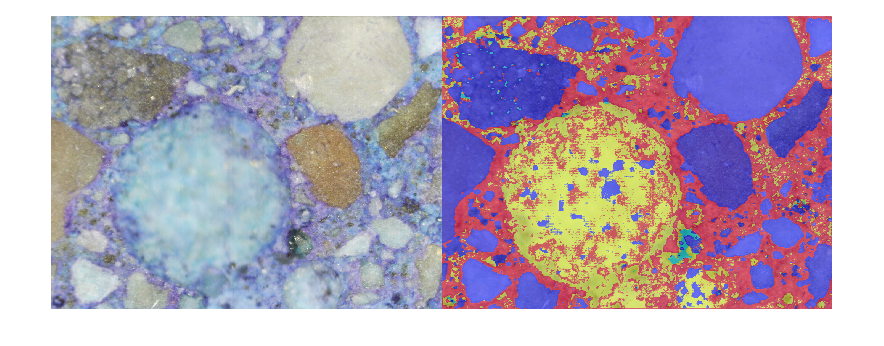


B = labeloverlay(I,C);
% imwrite(B,'images\segmentation_semantic.png')
imshowpair(I,B,'montage')

% saveas(gcf,'images\segmentation_semantic.png')
